# Optimización con restricciones no lineales de igualdad usando multiplicadores de Lagrange en MATLAB

**Alumno:** Pablo Ruiz Molina

### Representación del problema

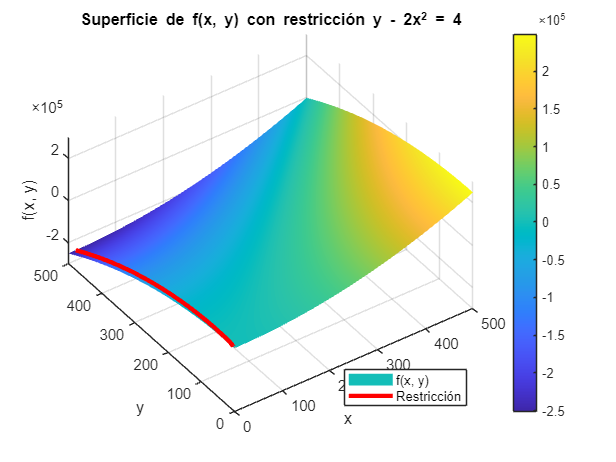

clc; clear; close all;

% Definir el rango de valores para x e y
x = linspace(0, 500, 1000);
y = linspace(0, 500, 1000);
[X, Y] = meshgrid(x, y);

% Definir la función objetivo
F = (X - 1).^2 - (Y + 1).^2;

% Graficar la superficie de la función
figure;
hold on;
surf(X, Y, F, 'EdgeColor', 'none'); % Superficie suave
colormap parula;
colorbar;

% Graficar la restricción y = 2*x^2 + 4 en 3D
y_restriccion = 2*x.^2 + 4;
f_restriccion = (x - 1).^2 - (y_restriccion + 1).^2;

plot3(x, y_restriccion, f_restriccion, 'r', 'LineWidth', 3);

% Etiquetas y título
xlabel('x');
ylabel('y');
zlabel('f(x, y)');
title('Superficie de f(x, y) con restricción y - 2x^2 = 4');
legend('f(x, y)', 'Restricción', 'Location', 'best');

xlim([0 500])
ylim([0 500])
zlim([-300000 300000])
view([-33 8])

grid on;
hold off;

## Resolución con multiplicadores de Lagrange

% Limpieza de la consola, variables y figuras
clc; clear; close all;

%% Definir la función objetivo y la restricción
syms x y lambda;

% Función objetivo
f = (x - 1)^2 - (y + 1)^2;

% Restricción
g = y - 2*x^2 - 4;

%% Definir la función Lagrangiana
L = f - lambda * g;

%% Calcular las derivadas parciales de la Lagrangiana
grad_L_x = diff(L, x);
grad_L_y = diff(L, y);
grad_L_lambda = diff(L, lambda);

%% Resolver el sistema de ecuaciones
% Crear el sistema de ecuaciones igualando las derivadas a cero
eqns = [grad_L_x == 0, grad_L_y == 0, grad_L_lambda == 0];
vars = [x, y, lambda];
solutions = solve(eqns, vars);

% Extraer soluciones
x_solutions = double(solutions.x);
y_solutions = double(solutions.y);
lambda_solutions = double(solutions.lambda);

% Mostrar las soluciones
disp('Puntos críticos:')

Puntos críticos:


for i = 1:length(x_solutions)
    fprintf('x = %.4f, y = %.4f, lambda = %.4f\n', x_solutions(i), y_solutions(i), lambda_solutions(i));
end

x = 0.0263, y = -0.7528, lambda = -0.4945
x = 0.0263, y = -0.7528, lambda = -0.4945
x = -0.0526, y = 4.0055, lambda = -10.0111


%% Evaluar el valor de la función objetivo en los puntos críticos
f_critical = double(subs(f, {x, y}, {x_solutions, y_solutions}));

% Mostrar los valores de la función objetivo en los puntos críticos
disp('Valores de la función objetivo en los puntos críticos:')

Valores de la función objetivo en los puntos críticos:


disp(f_critical)

  -1.4638 - 3.0827i
  -1.4638 + 3.0827i
 -23.9474 + 0.0000i




%% Calcular el Hessiano Orlado para clasificar los puntos críticos
% Definir el Hessiano de la Lagrangiana con respecto a x e y
H_L = [diff(grad_L_x, x), diff(grad_L_x, y); diff(grad_L_y, x), diff(grad_L_y, y)];

for i = 1:length(x_solutions)
    % Sustituir x, y y lambda en el Hessiano Orlado
    H_L_eval = double(subs(H_L, {x, y, lambda}, {x_solutions(i), y_solutions(i), lambda_solutions(i)}));
    grad_g = [diff(g, x); diff(g, y)];
    grad_g_eval = double(subs(grad_g, {x, y}, {x_solutions(i), y_solutions(i)}));
    
    % Crear el Hessiano Orlado
    H_orlado = [0, grad_g_eval.'; grad_g_eval, H_L_eval];
    
    % Mostrar el Hessiano Orlado
    fprintf('\nHessiano Orlado para el punto crítico (x = %.4f, y = %.4f):\n', x_solutions(i), y_solutions(i));
    disp(H_orlado);
    
    % Calculamos el determinante del Hessiano orlado
    det_H_orlado = det(H_orlado);
    
    % Mostramos el determinante del Hessiano orlado
    disp(['Determinante del Hessiano orlado: ', num2str(det_H_orlado)]);
    
    % Clasificación del punto crítico
    if det_H_orlado < 0
        disp('El punto crítico es un mínimo relativo.');
    elseif det_H_orlado > 0
        disp('El punto crítico es un máximo relativo.');
    else
        disp('El punto crítico es un punto de silla o requiere análisis adicional.');
    end    
end


Hessiano Orlado para el punto crítico (x = 0.0263, y = -0.7528):


   0.0000 + 0.0000i  -0.1051 - 6.1671i   1.0000 + 0.0000i
  -0.1051 - 6.1671i   0.0221 - 1.2968i   0.0000 + 0.0000i
   1.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 0.0000i



Determinante del Hessiano orlado: -76.0663+3.89049i


El punto crítico es un mínimo relativo.



Hessiano Orlado para el punto crítico (x = 0.0263, y = -0.7528):


   0.0000 + 0.0000i  -0.1051 + 6.1671i   1.0000 + 0.0000i
  -0.1051 + 6.1671i   0.0221 + 1.2968i   0.0000 + 0.0000i
   1.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 0.0000i



Determinante del Hessiano orlado: -76.0663-3.89049i


El punto crítico es un mínimo relativo.



Hessiano Orlado para el punto crítico (x = -0.0526, y = 4.0055):


         0    0.2103    1.0000
    0.2103  -38.0442         0
    1.0000         0   -2.0000



Determinante del Hessiano orlado: 38.1327


El punto crítico es un máximo relativo.
